clear;clc;close all;

Ra = 0.5; La = 0.01;
J = 1; B = 0.1;
Ke = 1.8; Kt = 1.8;
TL = 5;

Kp = 5;
Ki = 10;
omega_ref = 100;

dxdt = @(t, x)[...
    (( Kp*(omega_ref - x(2)) + Ki*x(3) ) - Ra*x(1) - Ke*x(2)) / La; ...
    (Kt*x(1) - B*x(2) - TL) / J; ...
    omega_ref - x(2) ...
    ];

tspan = [0 10];
x0 = [0;0;0];
[t,x] = ode45(dxdt, tspan, x0);

ia = x(:,1);
omega = x(:,2);

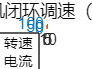

figure;
yyaxis left
plot(t, omega, "LineWidth",1.5);
ylabel('转速 (rad/s)')
yyaxis right
plot(t, ia, 'LineWidth',1.5);
ylabel('电流 (A)');
grid on;
xlabel('时间 (s)');
title('直流电机闭环调速（PI控制）');
legend('转速', '电流');